## Flower Classification Using Deep Learning

Guided Tutorial from MATLAB website

Callyn Villanueva (2019)

This example uses:

- [Deep Learning Toolbox](https://www.mathworks.com/help/deeplearning/index.html)

- [Deep Learning Toolbox Model for ResNet-50 Network](https://www.mathworks.com/help/deeplearning/ref/resnet50.html)

- [Statistics and Machine Learning Toolbox](https://www.mathworks.com/help/stats/index.html)

- [Computer Vision Toolbox](https://www.mathworks.com/help/vision/index.html)

- This guided example shows how to use a pretrained Convolutional Neural Network  (CNN) as a feature extractor for training an image category classifier. 

                               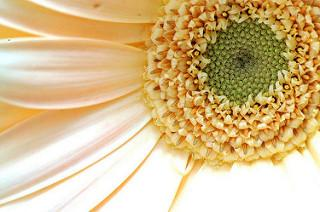

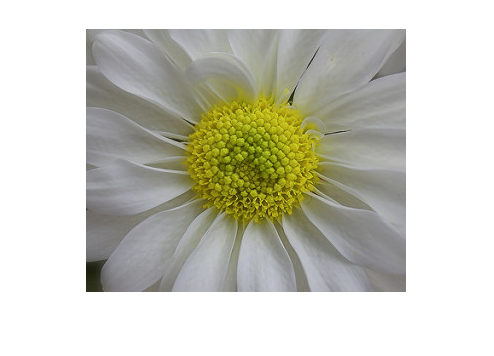


% Location of the compressed data set
url = 'http://download.tensorflow.org/example_images/flower_photos.tgz';

% Store the output in a temporary folder
downloadFolder = tempdir;
filename = fullfile(downloadFolder,'flower_dataset.tgz');

% Uncompressed data set
imageFolder = fullfile(downloadFolder,'flower_photos');

if ~exist(imageFolder,'dir') % download only once
    disp('Downloading Flower Dataset (218 MB)...');
    websave(filename,url);
    untar(filename,downloadFolder)
end

%Load the dataset using an ImageDatastore to help you manage the data. Because ImageDatastore operates on image file locations, 
% images are not loaded into memory until read,

imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);

% Find the first instance of an image for each category
daisy = find(imds.Labels == 'daisy', 1);

figure
imshow(readimage(imds,daisy))


%Use countEachLabel to summarize the number of images per category.
tbl = countEachLabel(imds)

tbl = 5×2 table
      Label       Count
    __________    _____

    daisy          633 
    dandelion      898 
    roses          641 
    sunflowers     699 
    tulips         799 



% imds above contains an unequal number of images per category, let's adjust it
% so that the number of images in the training set is balanced. To do this
% as follows:

% 1. Determine the smallest amount of images in a category
minSetCount = min(tbl{:,2}); 

% 2. Limit the number of images to reduce the time it takes.
maxNumImages = 100;
minSetCount = min(maxNumImages,minSetCount);

% 3. Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% 4. Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 5×2 table
      Label       Count
    __________    _____

    daisy          100 
    dandelion      100 
    roses          100 
    sunflowers     100 
    tulips         100 


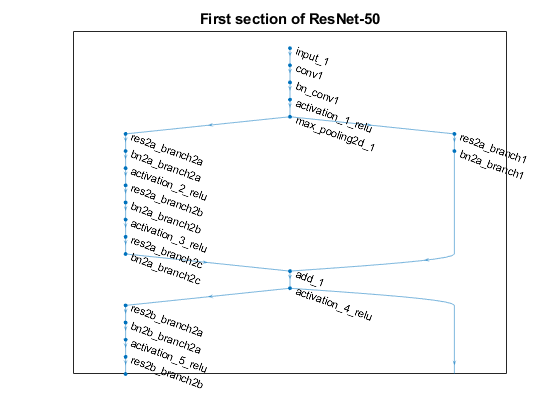



% loading a pretrained network
net = resnet50();

% Visualize the first section of the network. 
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);



%The first layer defines the input dimensions. Each CNN has a different input size requirements

% Inspect the first layer
net.Layers(1)

ans =   ImageInputLayer with properties:

                Name: 'input_1'
           InputSize: [224 224 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'
        AverageImage: [224×224×3 single]



% Inspect the last layer
net.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_fc1000'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


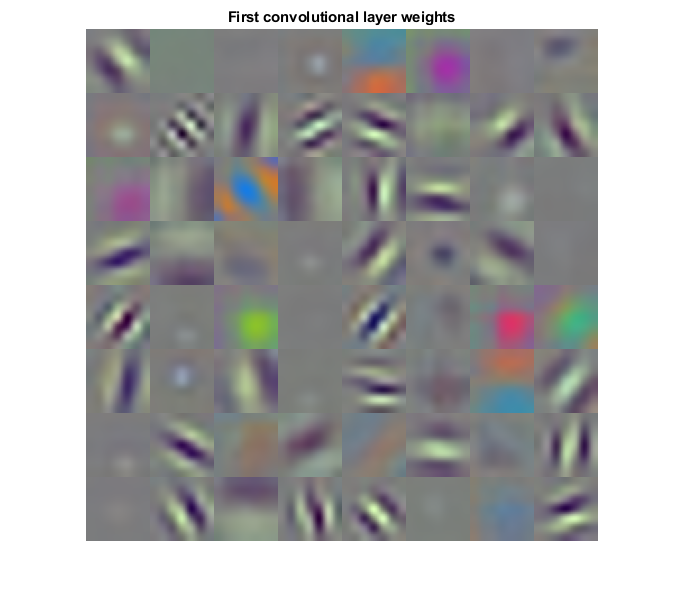


%Prepare Training and Test Image Sets

% Split the sets into training and validation data. Pick 30% of images from each set for the training data and the remainder, 70%, for the validation data. 
% Randomize the split to avoid biasing the results. 
% The training and test sets will be processed by the CNN model.

[trainingSet, testSet] = splitEachLabel(imds, 0.3, 'randomize');

% Pre-process Images For CNN

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, 'ColorPreprocessing', 'gray2rgb');

%Extract Training Features Using CNN

%Each layer of a CNN produces a response, or activation, 
% to an input image. However, there are only a few layers within a CNN that are suitable for image feature extraction. 
% The layers at the beginning of the network capture basic image features, such as edges and blobs. 
% To see this, visualize the network filter weights from the first convolutional layer.


% Get the network weights for the second convolutional layer
w1 = net.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5); 

% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w1)
title('First convolutional layer weights')


% Train A Multiclass SVM Classifier Using CNN Features

% % Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.
% Get training labels from the trainingSet

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');
trainingLabels = trainingSet.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.

classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'Linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns');


% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     0.8857    0.0286    0.0429         0    0.0429
    0.0143    0.9143    0.0143    0.0429    0.0143
         0    0.0286    0.8571    0.0429    0.0714
    0.0286    0.0714         0    0.8857    0.0143
    0.0286         0    0.1429    0.1000    0.7286




% Display the mean accuracy
mean(diag(confMat))

ans = 0.8543



%Applying trained classifier on one test 
testImage = readimage(testSet,1);
testLabel = testSet.Labels(1)

testLabel = categorical
     daisy 



% Create augmentedImageDatastore to automatically resize the image when
% image features are extracted using activations.
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');

% Extract image features using the CNN
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');


% Make a prediction using the classifier
predictedLabel = predict(classifier, imageFeatures, 'ObservationsIn', 'columns')

predictedLabel = categorical
     daisy 


testLabel = categorical
     daisy 
